# 状态估计

note1讨论了利用状态反馈时的控制律设计方法，然而我们如何获得这些状态的信息？这就需要我们使用状态估计器。

假设被控对象的状态空间表述为$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot x}} = {\mathbf{Ax}} + {\mathbf{B}}u} \\ 
  {y = {\mathbf{Cx}} } 
\end{array}} \right.\]$，我们可以构造一个相同的理论模型$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot \hat x}} = {\mathbf{A\hat x}} + {\mathbf{B}}u} \\ 
  {\hat y = {\mathbf{C\hat x}}} 
\end{array}} \right.\]$对输入产生响应，理论模型头上的帽子表示估计值，由于是理论模型，因此它的所有信息我们都可以知道。由于动态相同，我们似乎能够得到$\[{\mathbf{\hat x}} = {\mathbf{x}}\]$。实际上，如果我们不能够对系统的初始状态进行准确的估计（现实也往往如此），模型状态与实际状态的误差将会逐渐积累而导致状态估计失效。为了避免初始状态的影响，我们想起了那句控制的金律：***When in trouble, use feedback.***

## 全维状态估计器

我们利用实际输出与模型输出的误差对模型进行反馈校正：$\[{\mathbf{\dot \hat x}} = {\mathbf{A\hat x}} + {\mathbf{B}}u + {\mathbf{L}}\left( {y - \hat y} \right)\]$

此时状态估计的误差$\[{\mathbf{\tilde x}} = {\mathbf{x}} - {\mathbf{\hat x}}\]$满足：$\[{\mathbf{\dot \tilde x}} = \left( {{\mathbf{A}} - {\mathbf{LC}}} \right){\mathbf{\tilde x}}\]$

我们可以通过设计合理的$\[{\mathbf{L}}\]$使$\[{{\mathbf{A}} - {\mathbf{LC}}}\]$的特征值均具有负实部，从而使得状态误差收敛到0：估计的状态收敛到实际的状态。

状态观测器参数设计的方法与控制律完全相同，考虑数学关系：$\[\left| {{\mathbf{A}} - {\mathbf{LC}}} \right| = \left| {{{\left( {{\mathbf{A}} - {\mathbf{LC}}} \right)}^T}} \right| = \left| {{{\mathbf{A}}^T} - {{\mathbf{C}}^T}{{\mathbf{L}}^T}} \right| \leftarrow \left| {{\mathbf{A - BK}}} \right|\]$

则：状态观测器与控制律之间存在对偶关系，设计时只需分别将$\[{\mathbf{A}},{\mathbf{L}},{\mathbf{C}}\]$取转置后按控制律设计即可（设计完还需要转置回去）。

这里以note0给出的二阶系统为例，其状态空间表达为$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot x}} = \left[ {\begin{array}{*{20}{c}}
  0&1 \\ 
  { - \omega _n^2}&{ - 2\zeta \omega } 
\end{array}} \right]{\mathbf{x}} + \left[ {\begin{array}{*{20}{c}}
  0 \\ 
  {\omega _n^2} 
\end{array}} \right]u} \\ 
  {y = \left[ {\begin{array}{*{20}{c}}
  1&0 
\end{array}} \right]{\mathbf{x}}} 
\end{array}} \right.\]$。

设$\omega_n=1 {\rm \ rad/s, \ } \zeta=0.3$，我们利用simulink来构建该系统（见model1）。

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')
close all
clear;clc

T = 30;
Ts = 1e-3;
x0 = [0.3 0.1]';
uFlag = 0;
Lb = -0.2;       % 为了只仿真一次，提前设置降维状态观测器的参数，故意减缓收敛速度以看响应

wn = 1;
zeta = 0.3;
A = [0 1; -wn^2 -2*zeta*wn];
B = [0 wn^2]';
C = [1 0];

为了使估计的状态能观更快地收敛到真实状态，我们将状态估计器的阻尼设置为0.7，对应极点为：

p = [-0.7000+0.7141i -0.7000-0.7141i];
disp(p)

  -0.7000 + 0.7141i  -0.7000 - 0.7141i



L = place(A',C',p);
L = L';

配置极点后得到的$\[{\mathbf{L}}\]
$为：

disp(L)

    0.8000
   -0.4801



利用仿真，使被控对象初始状态非零，给定零输入情况下，实际状态和估计状态如下图所示，可见估计状态能够收敛于实际状态。

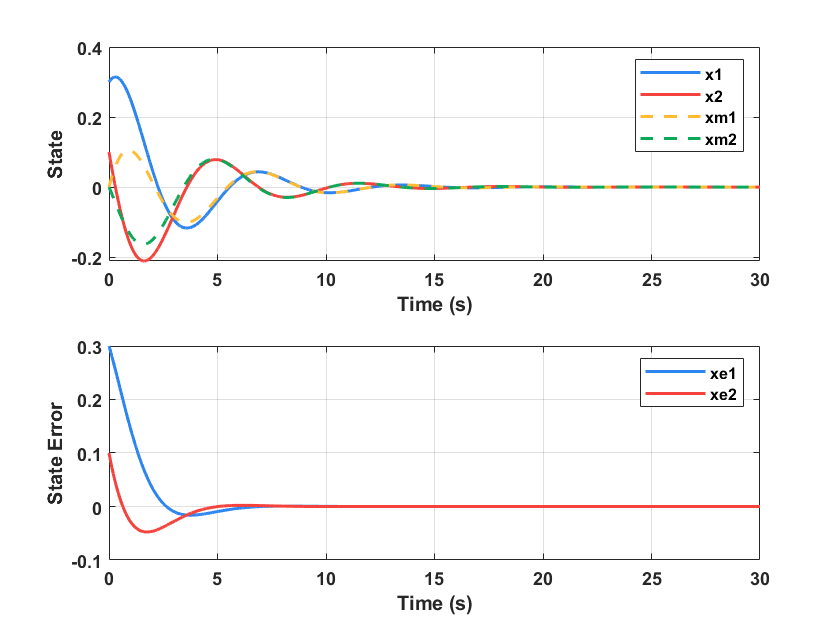

sim('model1_StateEstimator.slx')

figure
subplot(2,1,1)
plot(t,x)
hold on
plot(t,xm,'--')
grid on
legend('x1','x2','xm1','xm2')
xlabel('Time (s)')
ylabel('State')
subplot(2,1,2)
plot(t,x-xm)
grid on
legend('xe1','xe2')
xlabel('Time (s)')
ylabel('State Error')

## 降维状态估计器

上面介绍的状态估计器称之为全维状态估计器，因为它对系统的所有状态都进行了估计。然而，在一些情况下，系统的输出就是系统的某一个状态，那么我们能否直接利用这个状态，仅对其他状态进行估计呢？这时我们就需要用降维状态估计器。

我们以单输入单输出（SISO）系统为例讨论，不失一般性地，我们假设系统状态空间表达式为：

$\[\left\{ {\begin{array}{*{20}{l}}
  {\left[ {\begin{array}{*{20}{c}}
  {{{\dot x}_a}} \\ 
  {{{{\mathbf{\dot x}}}_b}} 
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
  {{A_{aa}}}&{{{\mathbf{A}}_{ab}}} \\ 
  {{A_{ba}}}&{{{\mathbf{A}}_{bb}}} 
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
  {{x_a}} \\ 
  {{{\mathbf{x}}_b}} 
\end{array}} \right] + \left[ {\begin{array}{*{20}{c}}
  {{B_a}} \\ 
  {{{\mathbf{B}}_b}} 
\end{array}} \right]u} \\ 
  {y = \left[ {\begin{array}{*{20}{c}}
  1&0 
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
  {{x_a}} \\ 
  {{{\mathbf{x}}_b}} 
\end{array}} \right]} 
\end{array}} \right.\]$，即表示系统的输出为状态$x_a$。

首先我们从$\[{{{{\mathbf{\dot x}}}_b}}\]$的关系中寻找系统方程：$\[{{{\mathbf{\dot x}}}_b} = {{\mathbf{A}}_{bb}}{{\mathbf{x}}_b} + \left( {{A_{ba}}{x_a} + {{\mathbf{B}}_b}u} \right)\]$

将$\dot x_a$换为输出的导数，改写系统的输出方程：$\[\left( {\dot y - {A_{aa}}{x_a} - {B_a}u} \right) = {{\mathbf{A}}_{ab}}{{\mathbf{x}}_b}\]$

上面两式的括号内的信息都是可知的，把它们看作降维观测器的输入、输出，类比全维观测中利用输出的误差进行反馈，有：


$$\[\begin{array}{c}
{{{\bf{\dot \hat x}}}_b} = {{\bf{A}}_{bb}}{{{\bf{\hat x}}}_b} + \left( {{A_{ba}}{x_a} + {{\bf{B}}_b}u} \right) + {{\bf{L}}_b}\left[ {\left( {\dot y - {A_{aa}}{x_a} - {B_a}u} \right) - {{\bf{A}}_{ab}}{{{\bf{\hat x}}}_b}} \right]\\
 = \left( {{{\bf{A}}_{bb}} - {{\bf{L}}_b}{{\bf{A}}_{ab}}} \right){{{\bf{\hat x}}}_b} + \left( {{A_{ba}} - {{\bf{L}}_b}{A_{aa}}} \right)y + \left( {{{\bf{B}}_b} - {{\bf{L}}_b}{B_a}} \right)u + {{\bf{L}}_b}\dot y
\end{array}\]$$


以此可构造降维状态估计器，但应注意，该状态观测器中含有$\dot y$，实际中微分是不容易做到的，且容易放大高频噪声，我们应当避免这一项的存在。因此，构造辅助状态$\[{{\mathbf{x}}_c} = {{{\mathbf{\hat x}}}_b} - {\mathbf{L}}_by\]$，则上式可改为：


$$\[{{\bf{\dot \hat x}}_c} = \left( {{{\bf{A}}_{bb}} - {{\bf{L}}_b}{{\bf{A}}_{ab}}} \right)\left( {{{\bf{x}}_c} + {{\bf{L}}_b}y} \right) + \left( {{A_{ba}} - {{\bf{L}}_b}{A_{aa}}} \right)y + \left( {{{\bf{B}}_b} - {{\bf{L}}_b}{B_a}} \right)u\]$$


我们只需要合理设计$ {{\bf{L}}_b}$使得$\[{{{\bf{A}}_{bb}} - {{\bf{L}}_b}{{\bf{A}}_{ab}}}\]$极点位于复平面左侧即可实现状态估计器的稳定。

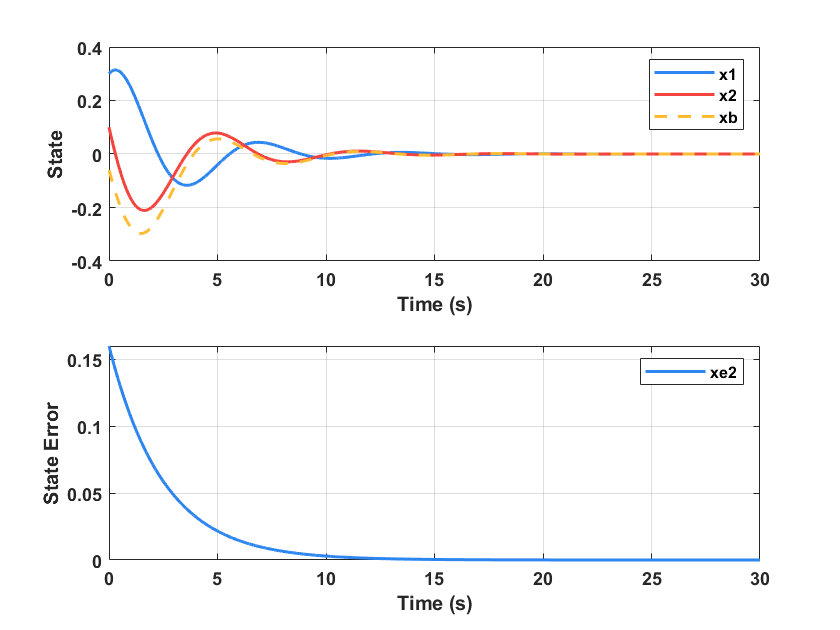

figure
subplot(2,1,1)
plot(t,x)
hold on
plot(t,xb,'--')
grid on
legend('x1','x2','xb')
xlabel('Time (s)')
ylabel('State')
subplot(2,1,2)
plot(t,x(:,2)-xb)
grid on
legend('xe2')
xlabel('Time (s)')
ylabel('State Error')

## 状态估计器讨论

***全维状态估计还是降维状态估计？***

全维状态估计器的所有状态响应都有一定的收敛过程，而降维状态估计器利用系统输出作为已知状态，该状态不受收敛过程的影响。

一般情况下还是推荐使用全维状态估计器，因为降维估计器中的已知状态容易受到传感器噪声的影响，而全维状态估计可以对噪声进行滤波，从而减少其影响。